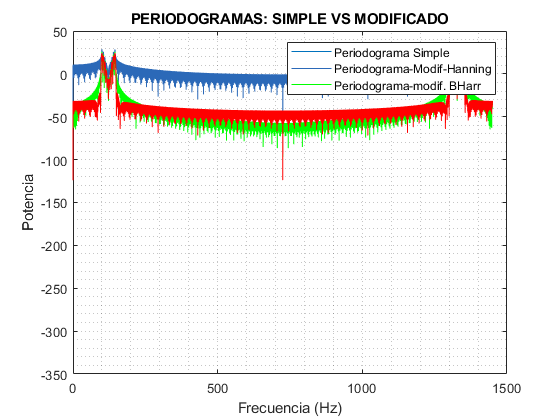

clc, close all;
 
duracion = 1;
fmax = 145;
Fs = 10*fmax;
t = 0 : 1/Fs : duracion; % Duración 10seg


xn = 1*sin(2*pi*100*t) + 0.5*sin(2*pi*105*t) + ...
  0.1*sin(2*pi*110*t) + 0.01*sin(2*pi*115*t) + ...
  0.001*sin(2*pi*120*t) + 0.001*sin(2*pi*125*t) + ...
  0.01*sin(2*pi*130*t) + 0.1*sin(2*pi*135*t) + ...
  0.5*sin(2*pi*140*t) + 1*sin(2*pi*145*t);
 
plot(t,xn);
 
N = length(xn);

%PERIODOGRAMA SIMPLE
nFFT = 2;
 
while nFFT < N
   nFFT = 32 * nFFT * 2;
end
 
% PERIODOGRAMA SIMPLE:
P1 = abs(fft(xn,nFFT));
f1 = linspace(0,Fs,nFFT);

% PERIODOGRAMA MODIFICADO:
 
% 1. GENERACION DE VENTANAS:
ventana_1 = rectwin(length(xn));
ventana_2 = hanning(length(xn));
ventana_3 = blackmanharris(length(xn));
 
 
% 2. Enventanado de la senial temporal:
y1_enventanada=xn.*ventana_1';
y2_enventanada=xn.*ventana_2';
y3_enventanada=xn.*ventana_3';
 
% 3. Periodograma simple vs modificado:
Pxx1=abs(fft(y1_enventanada,nFFT));
Pxx2=abs(fft(y2_enventanada,nFFT));
Pxx3=abs(fft(y3_enventanada,nFFT));
 
hold on 
plot(f1,10*log10(Pxx1),'Color',[0.17 0.41 0.72]);
plot(f1,10*log10(Pxx2),'g');
plot(f1,10*log10(Pxx3),'r');
title('PERIODOGRAMAS: SIMPLE VS MODIFICADO')
xlabel('Frecuencia (Hz)');
ylabel('Potencia');
legend('Periodograma Simple','Periodograma-Modif-Hanning','Periodograma-modif. BHarr')
axis([0 1500 -350 50])
grid minor

## METODOS PARAMETRICOS: AR

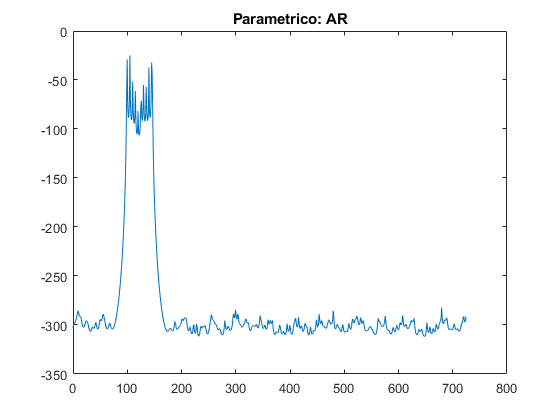


[Pb,fb]=pburg (xn, 300, N, Fs);
figure
plot(fb, 10*log10(Pb))
title('Parametrico: AR')

## Implementacion Propia

[Pb1, fb1] = mi_pburg (xn, 300, N, 'rectwin', Fs);
figure
plot(fb1, 10*log10(Pb1),"Color", [0.34 0.74 0.2])
title('Parametrico: AR mi pburg')

## Parametrico (de MatLab y Propio) y No parametrico Unidos

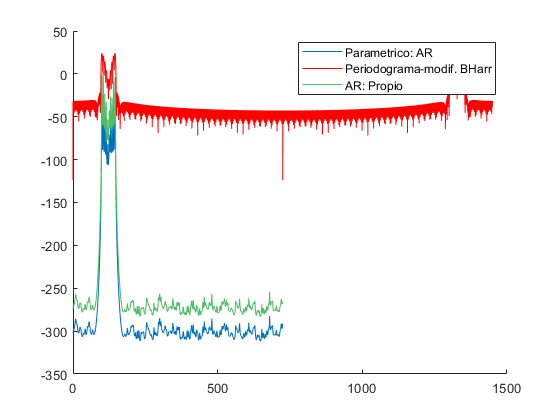


figure
hold on
plot(fb, 10*log10(Pb))
plot(f1,10*log10(Pxx3),'r')
plot(fb1, 10*log10(Pb1), 'Color', [0.3 0.74 0.4])
legend('Parametrico: AR','Periodograma-modif. BHarr', 'AR: Propio');